# Lab 5

1. Dùng máy ảnh quay 1 vật thể chuyển động, độ dài tầm 5-10s

v = VideoReader('video.avi');

% Lấy 15 frames đầu
frames = cell(100, 150);
for i = 1:15
    frames{i} = readFrame(v);
end

2. 

Lấy trung bình 15 frames đầu tiên -> Ảnh J2. 

Lưu ý điều chỉnh sao cho J2 nhoà

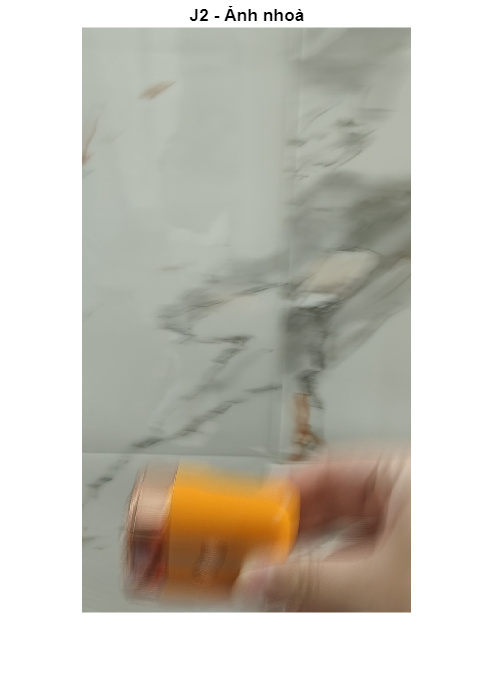

% Chuyển về double để tính trung bình
avg = zeros(size(frames{1}), 'double');
for i = 1:15
    avg = avg + double(frames{i});
end
avg = avg / 15;

% J2 là ảnh nhoà (trung bình)
J2 = uint8(avg);

% Chuyển sang grayscale
J2_gray = rgb2gray(J2);

figure;
imshow(J2); title('J2 - Ảnh nhoà');

3. Khử nhoà ảnh bằng: lowpass filter, box filter, gauss filter

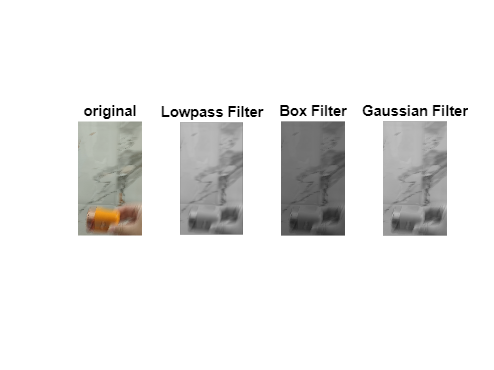

% Lowpass Filter
lpf = fspecial('average', 20); % bộ lọc trung bình 5x5
J_lowpass = imfilter(J2_gray, lpf);

% Box Filter
box = ones(5,5) / 40; % tương tự average
J_box = imfilter(J2_gray, box);

% Gaussian Filter
gauss = fspecial('gaussian', 7, 10); % kích thước 5x5, sigma=1
J_gauss = imfilter(J2_gray, gauss);

figure;
subplot(1,4,1); imshow(J2); title("original")
subplot(1,4,2); imshow(J_lowpass); title('Lowpass Filter');
subplot(1,4,3); imshow(J_box); title('Box Filter');
subplot(1,4,4); imshow(J_gauss); title('Gaussian Filter');

4. Khử nhoà ảnh bằng IFFT (k cần cài đặt lại)

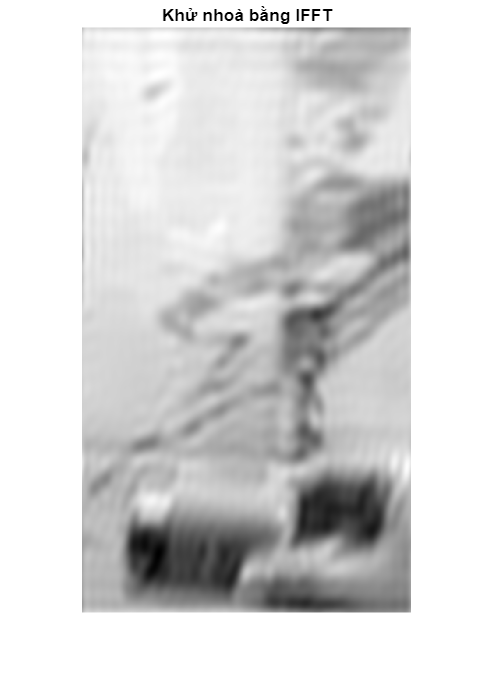

% FFT
F = fft2(double(J2_gray));
F_shift = fftshift(F);

% Tạo mask lowpass giữ tần số thấp
[M, N] = size(J2_gray);
[u, v] = meshgrid(-floor(N/2):floor(N/2)-1, -floor(M/2):floor(M/2)-1);
D = sqrt(u.^2 + v.^2);
D0 = 30; % bán kính cutoff
mask = double(D <= D0); % giữ tần số thấp

% Áp dụng mask và IFFT
F_filtered = F_shift .* mask;
F_ishift = ifftshift(F_filtered);
J_ifft = abs(ifft2(F_ishift));
J_ifft = uint8(mat2gray(J_ifft) * 255);

figure;
imshow(J_ifft); title('Khử nhoà bằng IFFT');

5. Tính đạo hàm theo phương x và phương y, cũng như gradient magnitude của ảnh J2

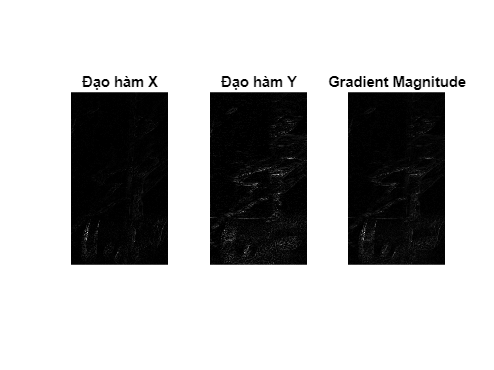

% Sobel kernels
Kx = 2 * [-1 0 1; -2 0 2; -1 0 1];
Ky = 2 * [-1 -2 -1; 0 0 0; 1 2 1];

J2_double = double(J2_gray);

% Thêm padding replicate để tránh lỗi biên
Gx = imfilter(J2_double, Kx, 'replicate');
Gy = imfilter(J2_double, Ky, 'replicate');

% Gradient magnitude
G_mag = sqrt(Gx.^2 + Gy.^2);

% Chuẩn hóa để hiển thị đúng
Gx_show = mat2gray(abs(Gx));
Gy_show = mat2gray(abs(Gy));
Gmag_show = mat2gray(G_mag);


figure;
subplot(1,3,1); imshow(Gx_show); title('Đạo hàm X');
subplot(1,3,2); imshow(Gy_show); title('Đạo hàm Y');
subplot(1,3,3); imshow(Gmag_show); title('Gradient Magnitude');

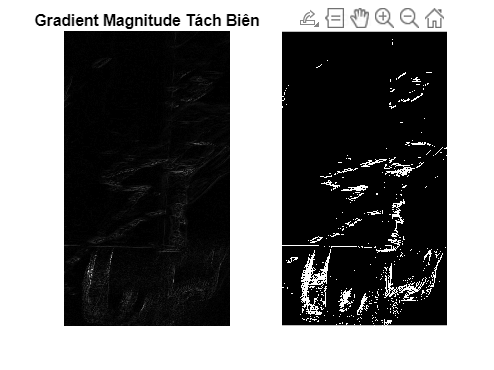

figure;
subplot(1,2,1); imshow(G_mag, []); title('Gradient Magnitude Tách Biên');

% Threshold để lấy biên rõ
G_edge = G_mag > 40;
G_edge = imdilate(G_edge, strel('disk',1));

subplot(1,2,2); imshow(G_edge); title('Biên rõ');

6. Tách biên bằng dialation của J2 (sử dụng kết hợp binarize, dialation, substraction)

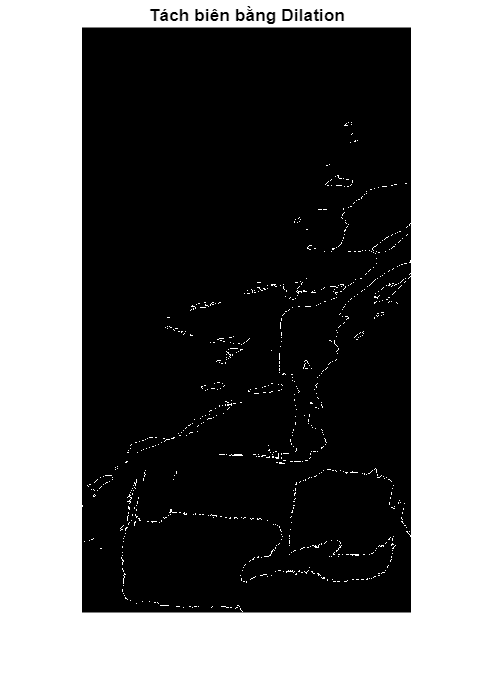

% Binarize J2
level = graythresh(J2_gray);
J2_bin = imbinarize(J2_gray, level);

% Dilation
se = strel('square', 3);
J2_dilate = imdilate(J2_bin, se);

% Biên = Dilation - Ảnh gốc
J_edge = imsubtract(J2_dilate, J2_bin);

figure;
imshow(J_edge); title('Tách biên bằng Dilation');

7. So sánh kq câu 5-6. Xem cái nào tách biên tốt hơn

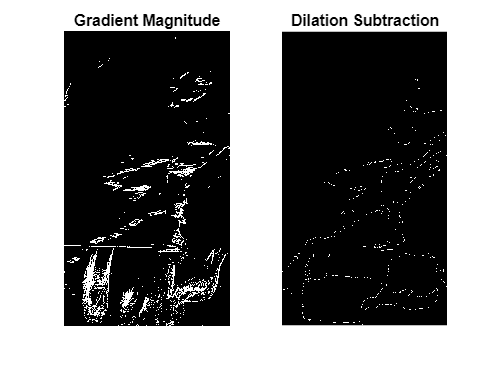

figure;
subplot(1,2,1); imshow(G_edge, []); title('Gradient Magnitude');
subplot(1,2,2); imshow(J_edge); title('Dilation Subtraction');